# Explore the Quaternion representation of angular pose

This tutorial demonstrates how to use the `bh_quat_rot_CLS` for representing the Quaternion approach of angular pose 

## **Import the package:**

import bh_rots_PKG.*

## A refresher on  DCM - via Euler angles

syms phi theta psi

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi],'SYM');

And look at what you have - here's the DCM

- $^Bv = {^BR_G}.^Gv$      where   $ {^BR_G} = 
R_{3X}(Roll) \enspace . \enspace 
R_{2Y}(Pitch)\enspace . \enspace R_{1Z}(Yaw)$   

tmp_R3R2R1 = OBJ_pass_rot.get_R3R2R1

$$tmp\_R3R2R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here are the 3 individual PASSIVE rotation matrices:

tmp_R1 = OBJ_pass_rot.get_R1

$$tmp\_R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

tmp_R2 = OBJ_pass_rot.get_R2

$$tmp\_R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

tmp_R3 = OBJ_pass_rot.get_R3

$$tmp\_R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Create a reference DCM - via Euler angles

#### Specify the angles

ref_yaw_deg   = 230;
ref_pitch_deg =  60;
ref_roll_deg  =  40;

ref_YPR_deg   = [ref_yaw_deg, ref_pitch_deg, ref_roll_deg];

#### Create the DCM

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, ref_YPR_deg,'DEGREES');
 
 ref_DCM_bRg  = OBJ_pass_rot.get_R3R2R1 

ref_DCM_bRg =    -0.3214   -0.3830   -0.8660
    0.2290   -0.9188    0.3214
   -0.9188   -0.0950    0.3830


Plot stuff

ans = 12.0018

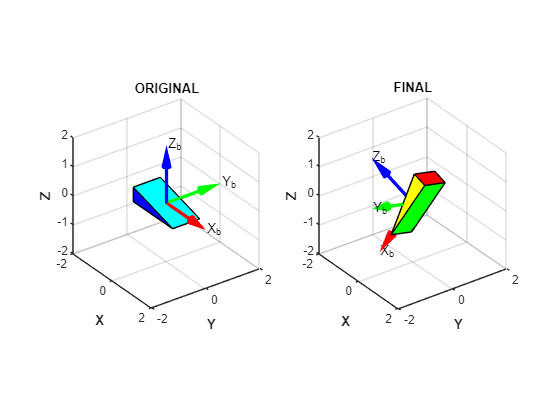

ans =     1.0020   12.0018


OBJ_pass_rot.plot_pair()

#### Create an Eigenaxis object from the DCM

OBJ_ee       = bh_eul_eigenaxis_CLS(ref_DCM_bRg)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.7614
    DCM_B_given_A: [3×3 double]
        theta_deg: 158.2184
           e_axis: [0.5611 -0.0712 -0.8247]
      vis_DCM_bRg: [3×3 double]



ee_col       = OBJ_ee.e_col

ee_col =     0.5611
   -0.0712
   -0.8247


ee_theta_rad = OBJ_ee.theta_rad

ee_theta_rad = 2.7614

## Explore the quaternion representation

Create a `bh_quat_rot_CLS` object

 OBJ_quat_rot = bh_quat_rot_CLS();

### If I have an Eigenaxis can I compute q :

[ref_q_col, q_xyz]  = OBJ_quat_rot.calc_q_from_eigenaxis(OBJ_ee.e_col, OBJ_ee.theta_rad) 

ref_q_col =     0.1889
    0.5510
   -0.0699
   -0.8098


q_xyz =     0.5510
   -0.0699
   -0.8098


### Compute the DCM from the quaternion

tmp_DCM = OBJ_quat_rot.calc_dcm_from_q(ref_q_col);

should_be_zero = ref_DCM_bRg - tmp_DCM;

[ should_be_zero,  ref_DCM_bRg ]

ans =    -0.0000   -0.0000    0.0000   -0.3214   -0.3830   -0.8660
   -0.0000    0.0000    0.0000    0.2290   -0.9188    0.3214
    0.0000    0.0000    0.0000   -0.9188   -0.0950    0.3830


### Compute Yaw, Pitch and Roll from the quaternion

[my_yaw, my_pitch, my_roll] = OBJ_quat_rot.calc_yaw_pitch_roll_from_q(ref_q_col);

rad2deg( [my_yaw, my_pitch, my_roll] )

ans =  -130.0000   60.0000   40.0000


 **NOTE: ** the difference for the YAW angle is 360 degrees .... which is also acceptable

should_be_zero = [ref_yaw_deg, ref_pitch_deg, ref_roll_deg] - rad2deg( [my_yaw, my_pitch, my_roll] )

should_be_zero =   360.0000   -0.0000    0.0000


### Compute the Eigenaxis parameters from the quaternion

[ tmp_E_col, tmp_theta_rad] = OBJ_quat_rot.calc_eigenaxis_from_q(ref_q_col)

tmp_E_col =     0.5611
   -0.0712
   -0.8247


tmp_theta_rad = 2.7614


should_be_zero = OBJ_ee.e_col - tmp_E_col

should_be_zero =      0
     0
     0



[OBJ_ee.e_col,  should_be_zero ]

ans =     0.5611         0
   -0.0712         0
   -0.8247         0


### If I have a DCM can I compute q :

tmp_q = OBJ_quat_rot.calc_q_from_dcm(ref_DCM_bRg)

tmp_q =    -0.1889
   -0.5510
    0.0699
    0.8098


 **NOTE: ** see below for an explanation on WHY these are different !

[ref_q_col,  tmp_q]

ans =     0.1889   -0.1889
    0.5510   -0.5510
   -0.0699    0.0699
   -0.8098    0.8098


[ tmp_E_col, tmp_theta_rad] = OBJ_quat_rot.calc_eigenaxis_from_q(tmp_q)

tmp_E_col =    -0.5611
    0.0712
    0.8247


tmp_theta_rad = 3.5218

**NOTE sometimes:**

- `tmp_q` is not identical to `ref_q_col`

- `tmp_E_col` and `tmp_theta_rad` are NOT identical to `OBJ_ee.e_col`, `OBJ_ee.theta_rad`

When this occurs, what we're seeing here are equivalent ways of viewing the rotated frames.  If $\theta >\pi \;$ then we can ALSO construct the IDENTICAL transformation from ($\theta =\theta -2\pi \;$).  So convert the existing quaternion into a NEW quaternion that represents the same identical transformation for $\theta$ in the interval $\left\lbrack \;-\pi \;,\;\pi \;\right\rbrack$

q_out = OBJ_quat_rot.calc_q_pm_pi_from_q(tmp_q)

q_out =     0.1889
    0.5510
   -0.0699
   -0.8098


[ tmp_E_col, tmp_theta_rad] = OBJ_quat_rot.calc_eigenaxis_from_q(q_out)

tmp_E_col =     0.5611
   -0.0712
   -0.8247


tmp_theta_rad = 2.7614

### If I have a ROLL, PITCH and YAW can I compute q :

tmp_q = OBJ_quat_rot.calc_q_from_YPR( deg2rad(ref_yaw_deg), deg2rad(ref_pitch_deg), deg2rad(ref_roll_deg) )

tmp_q =    -0.1889
   -0.5510
    0.0699
    0.8098


And we should be able to reverse it:

[tmp_yaw, tmp_pitch, tmp_roll] = OBJ_quat_rot.calc_yaw_pitch_roll_from_q(tmp_q);

rad2deg( [tmp_yaw, tmp_pitch, tmp_roll] )

ans =  -130.0000   60.0000   40.0000


## Compute a vector in Body frame:

G_col       = [12;13;78];

B_col       = ref_DCM_bRg * G_col

B_col =   -76.3860
   15.8719
   17.6143



q_col       = OBJ_quat_rot.calc_q_from_dcm(ref_DCM_bRg)

q_col =    -0.1889
   -0.5510
    0.0699
    0.8098



B_col_again = OBJ_quat_rot.convert_Gvec_to_Bvec(q_col, G_col)

B_col_again =   -76.3860
   15.8719
   17.6143


### Compare

Compare these results against those in the Aerospace Toolbox:

- [`quatrotate`](matlab:  web(fullfile(docroot, 'aerotbx/ug/quatrotate.html'))) and [`dcm2quat`](matlab:  web(fullfile(docroot, 'aerotbx/ug/dcm2quat.html')))

q_a = dcm2quat(ref_DCM_bRg)

q_a =    -0.1889   -0.5510    0.0699    0.8098



B_a = quatrotate(q_a, G_col')

B_a =   -76.3860   15.8719   17.6143


Is `q_a` really a UNIT quaternion ?

norm(q_a)

ans = 1.0000

# Local subfunctions only beyond this point